clear; close all; clc

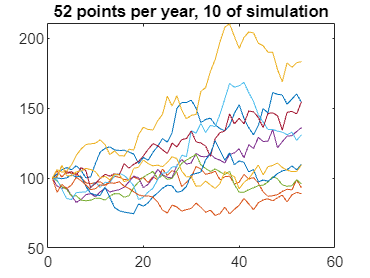

N = 52; NS = 10;
S = simulate_stockprice(N, NS);
figure;
plot(S')
prefix = sprintf("%d points per year, %d of simulation", N, NS);
title(prefix)

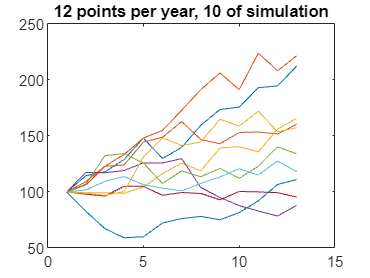

N = 12; NS = 10;
S = simulate_stockprice(N, NS);
figure;
plot(S')
prefix = sprintf("%d points per year, %d of simulation", N, NS);
title(prefix)

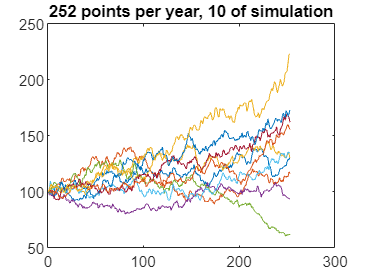


N = 252; NS = 10;
S = simulate_stockprice(N, NS);
figure;
plot(S')
prefix = sprintf("%d points per year, %d of simulation", N, NS);
title(prefix)

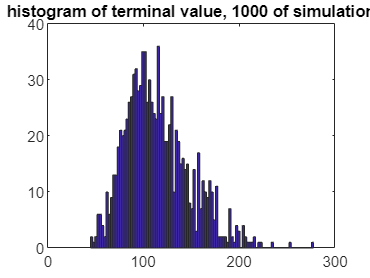

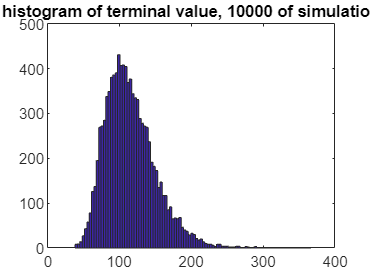

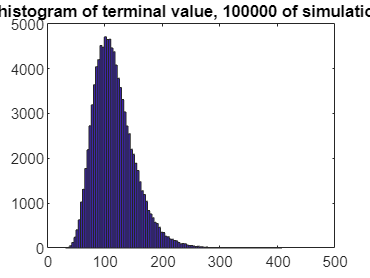

N = 52; NSs = [1000, 10000, 100000];
for i = 1:3
    S = simulate_stockprice(N, NSs(i));
    figure;
    hist(S(:,end), 100)
    prefix = sprintf("histogram of terminal value, %d of simulation", NSs(i));
    title(prefix)
end

function S= simulate_stockprice(N, NS)
    T = 1;
    %N = 52; %points per year
    dt = T/N;
    
    sigma = 0.3;
    mu = 0.15;
    S0 = 100;
    
    %NS = 10; % number of simulations 
    dS = zeros(NS, N*T);
    dZ = randn(NS, N*T)*sqrt(dt);
    S = zeros(NS, N*T+1);
    S(:,1) = S0;
    
    for i = 1:NS
        for j = 1:N*T
            dS = S(i,j) * (mu*dt+sigma*dZ(i,j));
            S(i, j+1) = S(i,j) + dS;
        end
    end
end